## Introduction to Environmental Data Analysis and Statistical Learning Exercise 7 – Entropy

Chow Ka Hei Pinky

clear all
close all
clc

load ue_07_entropy_data
whos

  Name                       Size             Bytes  Class     Attributes

  Q_COL                  37110x1             296880  double              
  Q_USL                  37110x1             296880  double              
  TETA_S_D_VWC_10_A      37110x1             296880  double              



SD = TETA_S_D_VWC_10_A;

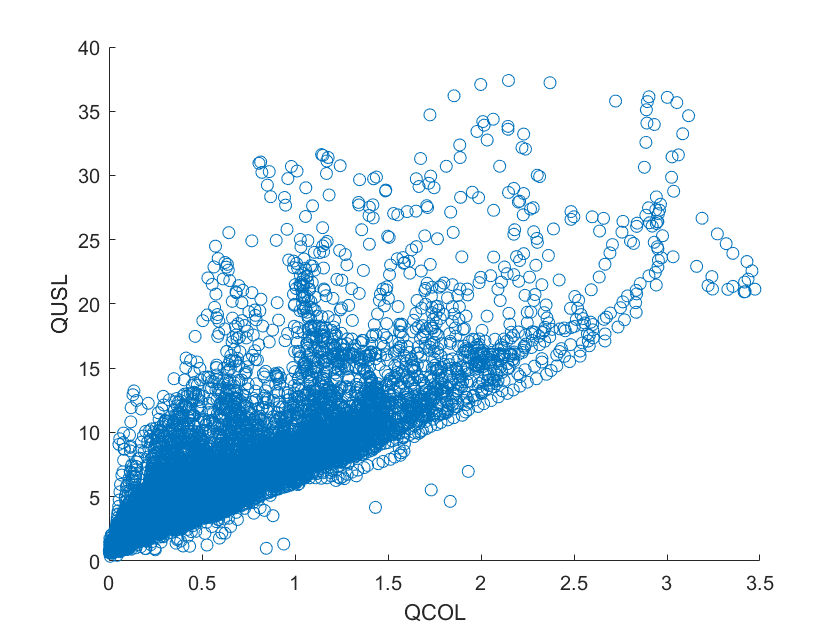

%Visualizing the data before further processing
scatter(Q_COL, Q_USL)
xlabel("QCOL")
ylabel("QUSL")

### Entropy of discharge Q_USL

%Calculating entropy by calling the defined function 1
[occurence, bin_edges] = histcounts(Q_USL, 55,'BinLimits',[0,55]);
Q_USL_entropy = entropy(occurence,length(Q_USL))

Q_USL_entropy = 3.1191

### Conditional Entropy for Q_USL with predictors discharge Q_COL and Soil Water Content SD

%Establishing 2D bin counts and calling the function 2 conditional entropy

%Q_COL = predictor = every row; Q_USL = target = every column
[occurence2D_Q,Xedges1,Yedges1] = histcounts2(Q_COL,Q_USL, [10 55], ...
    'XBinLimits',[0,3.5], 'YBinLimits',[0,55]);
condH_preCOL = conditional_entropy(occurence2D_Q)

condH_preCOL = 2.3230


%SD = predictor = every row; Q_USL = target = every column
[occurence2D_SD,Xedges2,Yedges2] = histcounts2(SD,Q_USL, [10 55], ...
    'XBinLimits',[0.12,0.45], 'YBinLimits',[0,55]);
condH_preSD = conditional_entropy(occurence2D_SD)

condH_preSD = 2.3841


display("Results: The conditional entropy Q_USL|Q_COL is:" + ...
    " "+condH_preCOL+", " + ...
    "and Q_USL|SD is: "+condH_preSD)

    "Results: The conditional entropy Q_USL|Q_COL is: 2.323, and Q_USL|SD is: 2.3841"




if condH_preCOL > condH_preSD
    display("The predictor which leads to a lower conditional entropy of Q_USL is: SD")
elseif condH_preCOL == condH_preSD
    display("Both conditional entropy are the same.")
else
    display("The predictor which leads to a lower conditional entropy of Q_USL is: Q_COL")
end

    "The predictor which leads to a lower conditional entropy of Q_USL is: Q_COL"



### Discussion

#### 1. Which predictor is more informative?

The information of Q_USL revealed by the entropy is originally 3.12 bit. The knowing of predictor reduce the uncertainty of Q_USL and hence the "surprise" of the Q_USL will be reduced. Generally, the conditional entropy will be smaller then the entropy, which is also the case in this calculation.

By knowing Q_COL, the "surprise" is being reduced from 3.12 bit to 2.32 bit; by knowing SD, the "surprise" is being reduced from 3.12 to 2.38 bit. The sharper the dropping of entropy, the more helpful is the information of the predictor in helpping to figure out the target (Q_USL).

Hence, the knowing of Q_COL is a better prediction of Q_USL. It is more informative and contains above **3.12 - 2.32 = 0.8 bit of information in Q_USL**. In contrast, SD soil water content is less informative about Q_USL and only contains 3.12 - 2.38 = 0.74 bit information about Q_USL. To increase cost effectiency with the goal of predicting Q_USL, I will only **keep the sensor of Q_COL**, and abodon the sensor of SD.

#### 2. How valuable is knowledge of the distribution of Q_USL?

%Maximum entropy guess of Q_USL
datapoint = length(Q_USL)

datapoint = 37110

bin_edges_uni = 0:1:55

bin_edges_uni =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


occurence_uni = ones(1,55).*(datapoint/55)

occurence_uni =   674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273  674.7273


Q_USL_entropy_uni = entropy(occurence_uni,length(Q_USL))

Q_USL_entropy_uni = 5.7814


%The difference between Q_USL distribution and uniform distribution
display("Uniform distribution: "+Q_USL_entropy_uni+" bits")

    "Uniform distribution: 5.7814 bits"



display("Q_USL distribution: "+Q_USL_entropy+" bits")

    "Q_USL distribution: 3.1191 bits"



display("Difference: "+(Q_USL_entropy_uni - Q_USL_entropy)+" bits")

    "Difference: 2.6622 bits"



Hence, the value of knowing the distribution of Q_USL, depending on the difference between maximum entropy and the actual entropy, is **2.66 bit information**. It is almost half of it so the information of the actual distribution is considered valuable.

#### 3. Compare the information gains between knowing:

− only the default uniform distribution assumption of Q_USL: **5.7814 bits**

− the observed distribution of Q_USL:** 3.1191 bits**

− additionally knowing your preferred predictor: **2.32 bits**

In the uniform distribution, all scanerios have same probability to occur and thus the information is the highest (5.78 bits) since there is no "hint" to guess what is more probable. After knowing the actual distribution, we gain information about the frequency distribution of the event which is equivalent to 2.66 bits information. Thus, we have less information from the Q_USL values since we have less "surprise". In addition, we can make use of the predictor to further gain information about Q_USL. With the information from Q_COL which acts as a good predictor, we can gain 0.8 bit of information and hence the conditional entropy of Q_USL will further reduced to only 2.32 bits, which means that we can be already quite sure about what is the actual values of Q_USL compared to the previous uniform distribution. We gain, at this point, alomst 40% of the information from the actual distribution and the predictor values. 

### Functions for the Calculation of Entropy and Conditional Entropy

function cen = conditional_entropy(occurence_matrix) 
% the second function for conditional entropy

%Explainations
% the input is a two-dimensional matrix, which illustrates the
% frequency of the bin counts in x (target) with different ranges of predictor values in y.
%𝐻(𝑋|𝑌) = sum(p(𝑦𝑗)*𝐻(𝑋|𝑌 = 𝑦𝑗)), y = predictor, x = target

    cen = 0;
    f_everypredictor = sum(occurence_matrix,2); %the sum of every row (predictor)
    ALL = sum(occurence_matrix,"all"); %the sum of the total data in the matrix
    for j = 1:size(occurence_matrix,2) %from column 1 to 55
        for i = 1:size(occurence_matrix,1) %from rows 1 to 10
            if occurence_matrix(i,j) ~= 0 %exclude zeros value to avoid errors from running
                pyj = f_everypredictor(i)/ALL; %marginal probability
                pxij = occurence_matrix(i,j)/f_everypredictor(i); %normalization of value
                addup = pyj*log2(pxij)*(pxij); %the conditional entropy formula
                cen = cen + abs(addup); %add up the absolute value
            else
            end
        end
    end
end


function en = entropy(o,tot) 
% the first function for entropy

%Explainations
% the first input is a frequency vector, the second input
% is the total number of data being put into the bins.
    en = 0;
    for i = 1: length(o)
        if o(i) ~= 0
            en = en + ((-log2(o(i)/tot))*(o(i)/tot));
        else
        end
    end
end

